% Martedi 03 Novembre 2020 - Mercoledi 04 Novembre 2020
% Corso di Elaborazione dei Segnali e Immagini
% Docente: Ilaria Boscolo Galazzo 
% Docente Coordinatore: Marco Cristani
% Tutor lab: Christian Joppi 
% LAB2 - parte 2

clear all
close all
clc

## Esercizio 1 - Cross-correlazione 2D normalizzata per trovare difetti su tessuti

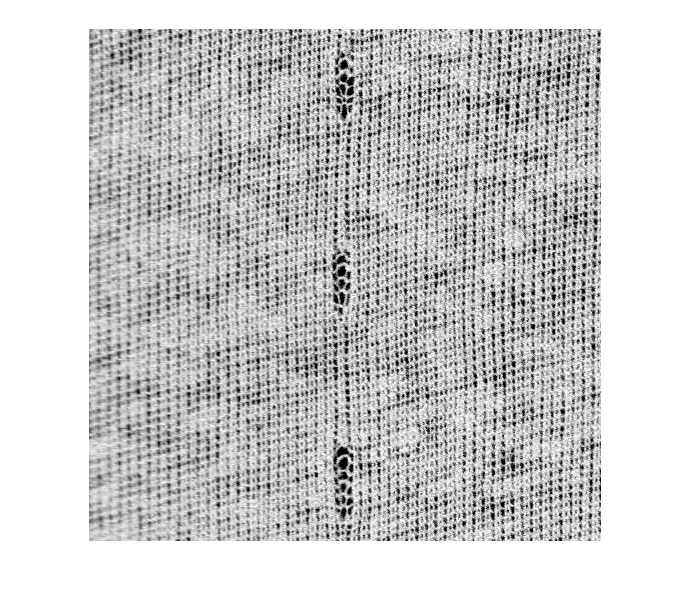

B= rgb2gray(imread('i7.jpg'));
[R,C]=size(B);

%Aumento contrasto con imadjust con stretchlim che imposta automaticamente
%la soglia minima del contrasto
A = imadjust(B,stretchlim(B),[]);
figure;
imshow(A);

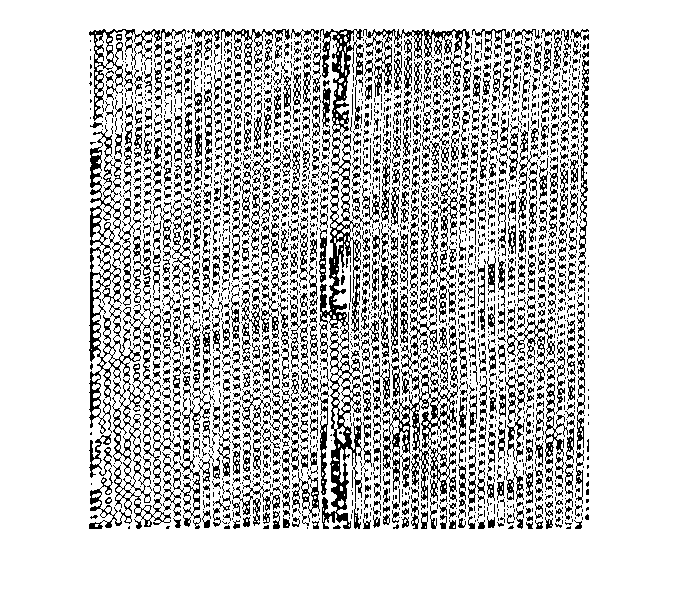

%

% Definisco una serie di pattern, tutti quadrati 14x14
pattern1 = A(1:28,1:28); 
pattern2 = A(2:29,2:29);
pattern3 = A(R-28:R-1,C-28:C-1);
pattern4 = A(R-29:R-2,C-29:C-2);
pattern5 = A(R-28:R-1,1:28);
pattern6 = A(R-29:R-2,2:29);
pattern7 = A(1:28,C-28:C-1);
pattern8 = A(2:29,C-29:C-2);

figure;
imagesc(A); axis image; colormap gray; hold on;
rectangle('position',[1,1,14,14],'EdgeColor','r'); % pattern1
rectangle('position',[2,2,14,14],'EdgeColor','g'); % pattern2
rectangle('position',[R-13,C-13,14,14],'EdgeColor','b'); %pattern3
rectangle('position',[R-14,C-14,14,14],'EdgeColor','c'); %pattern4
rectangle('position',[1,C-13,14,14],'EdgeColor','m'); %pattern5
rectangle('position',[2,C-13,14,14],'EdgeColor','k'); %pattern6

% Calcolo la xcorr-2D (normalizzata). Size = N+M-1
c1 = normxcorr2(pattern1,A); % 525x525
c2 = normxcorr2(pattern2,A);
c3 = normxcorr2(pattern3,A);
c4 = normxcorr2(pattern4,A);
c5 = normxcorr2(pattern5,A);
c6 = normxcorr2(pattern6,A);
c7 = normxcorr2(pattern7,A);
c8 = normxcorr2(pattern8,A);

% From MATLAB Help:
% C = normxcorr2(TEMPLATE,A) computes the normalized cross-correlation of
%     matrices TEMPLATE and A. The matrix A must be larger than the matrix
%     TEMPLATE for the normalization to be meaningful. The values of TEMPLATE
%     cannot all be the same. The resulting matrix C contains correlation
%     coefficients and its values may range from -1.0 to 1.0.

c = (c1+c2+c3+c4+c5+c6+c7+c8)/8; % calcolo media (525x525)
c = c(20:end-20,20:end-20);
figure, surf(abs(c)), shading flat
figure, imagesc(abs(c)), colorbar
c=abs(c);

% Graythreshold
lv = graythresh(c);
maskt = c > (lv / 2 );
figure; 
imshow(maskt);

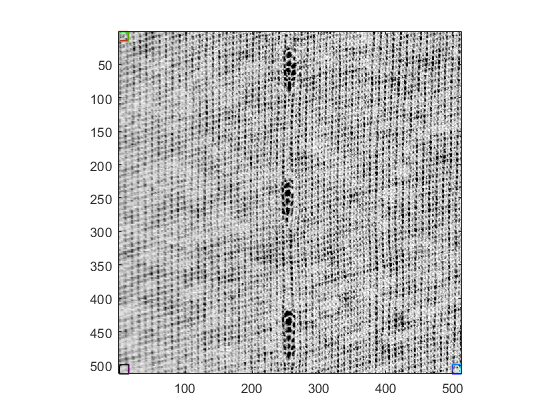

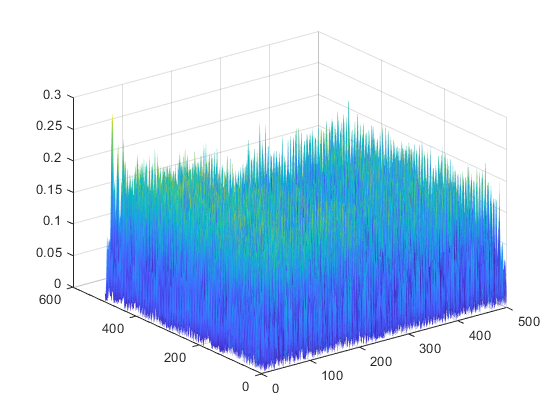

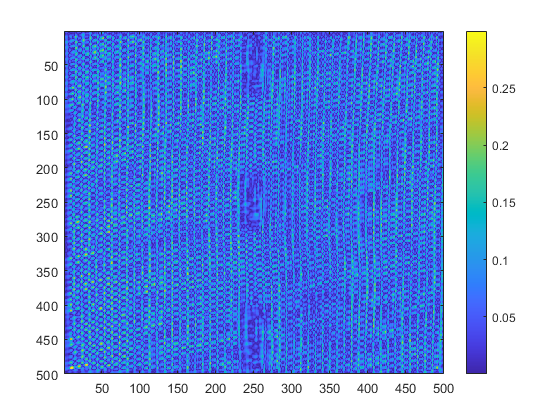

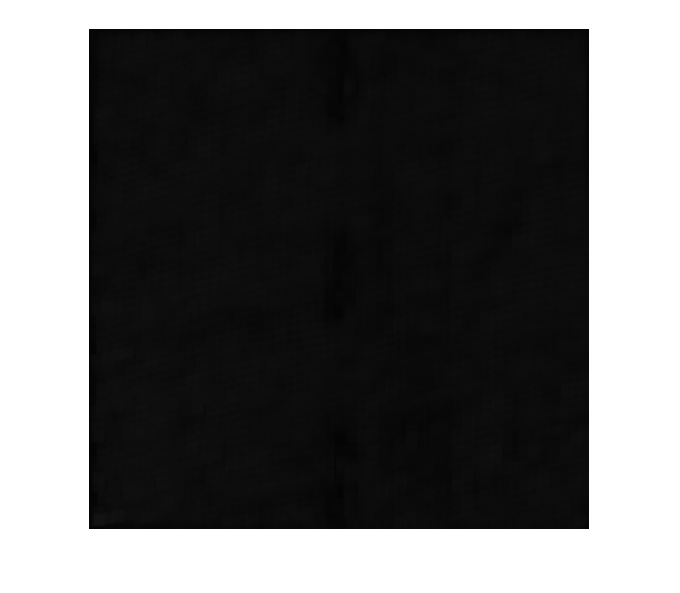

%Filtro deviazione standard
sf = stdfilt(c ,ones(11));
figure;
imshow(sf);

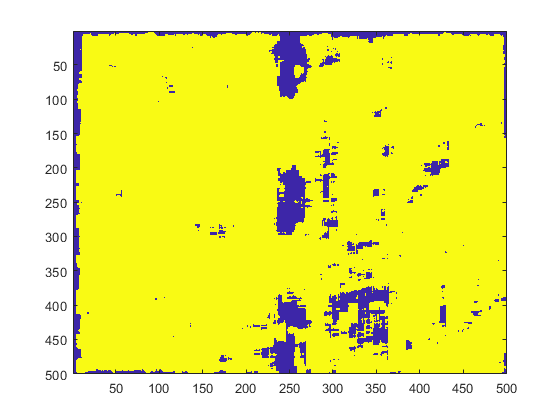

mask = sf > (lv / 2);

%mask = c < 0.2;
figure, imagesc(mask);

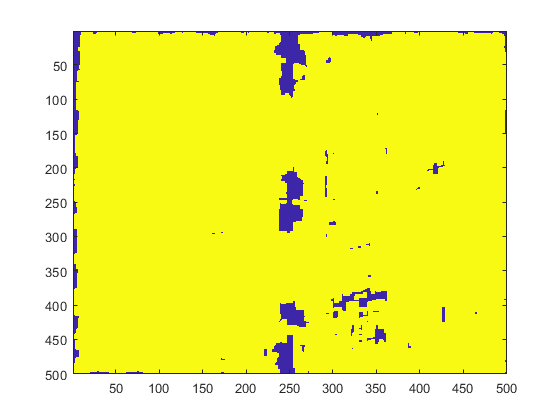

se = strel('disk',3); % crea un disco con R = 3%
mask2 = imdilate(mask,se); %Questo è meglio per ora
%mask2 = imopen(mask2,se);
figure, imagesc(mask2);



%mask2 = imsubtract(imadd(mask2,imtophat(mask2,se)),imbothat(mask2,se));

Error using imsubtract (line 58)
X and Y must have the same size and class, or Y must be a scalar double.


mask2 = bwareafilt(mask2,5,'largest');

mask2 = imcomplement(mask2);
figure, imagesc(mask2);

% Nota per IMOPEN = Perform morphological opening.
% The opening operation erodes an image and then dilates the eroded image,
% using the same structuring element for both operations.
% Morphological opening is useful for removing small objects from an image
% while preserving the shape and size of larger objects in the image.

A=A(6:end-7,6:end-7); % Passo da 512x512 a 500x500
A1 = A;
A1(mask2)=255;
Af=cat(3,A1,A,A);
figure;
imshowpair(A,Af,'montage')